# Bisection Method

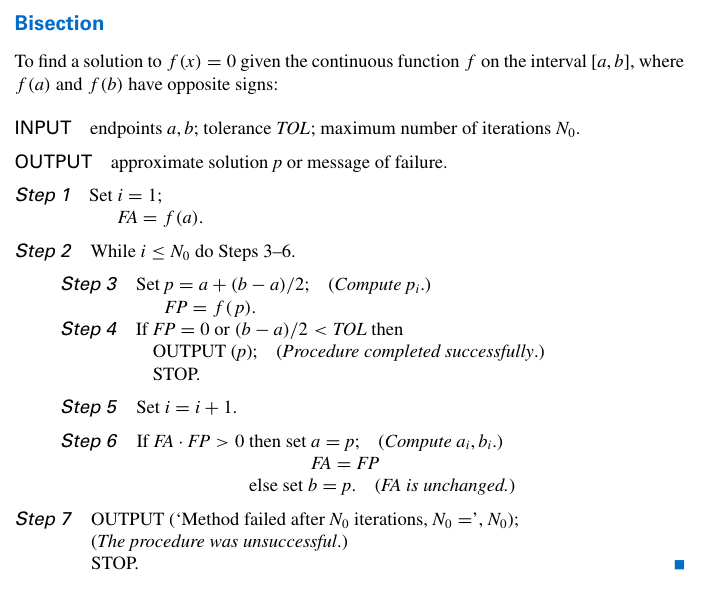

## Initialization

clc;
clear;
close all; %Clear before

## Add initial condition

tol = 1.e-3;            % Tolorence of result
a = 2;                  % Initial left value
b = 3;                  % Initial right value
nmax = 100;             % Number of initialization iterations
itcount = 0;            % Number of initialization iterations
error = 10000;          % Error initialization         

Plot the graph


xval = linspace(a,b,100);
for i=1:100
    fval(i) = func(xval(i));        % Calculate function image points
end
plot(xval,fval);                    % Plot the function

Calculate through the bisection method 开始计算点位:

grid on;
hold on;
while (itcount <= nmax && error >=tol)      % When the number of iterations does not overflow, the error is still too large
    itcount =itcount+1;
    x=(a+b)/2;                              % Iteration function of the Bisection Method
    z(itcount)=x;                           % Record the result into the dataset
    fa=func(a);
    fx=func(x); 
    error=abs(a-x)/(abs(x)+eps); %keep the denominator not to be 0
    if (error < tol)
        x_final = x;
    elseif (fa*fx <0)
        b = x;
    else
        a = x;
    end
end

Plot the Graph 绘制图像

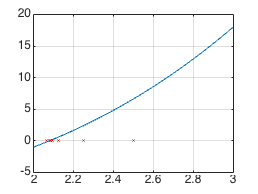

plot(z(1:itcount),zeros(itcount,1),'rx');

if (itcount <nmax)
    val = func(x);
    fprintf('Converged solution after %d iterations',itcount);
    fprintf(' is %.7e\n',x_final);
else
    fprinf('Not converged after %5d iterations',namx);
end

Converged solution after 9 iterations

 is 2.0800781e+00
